lidar = serialport("COM1", 115200);
maxLidarRange = 8;
mapResolution = 20;
maxNumScans = 1;
slamAlg = lidarSLAM(mapResolution, maxLidarRange, maxNumScans);
slamAlg.LoopClosureThreshold = 210;  
slamAlg.LoopClosureSearchRadius = 8;
Angles = {};
Ranges = {};

while true
    if lidar.NumBytesAvailable > 0
        data = read(lidar,2000,"uint8"); 
        
        indicesOfHeader = strfind(data,[170 85]);
        packets = {};
        for i = 1:length(indicesOfHeader)-1
            startIdx = indicesOfHeader(i);
            endIdx = indicesOfHeader(i+1);
            packets{end+1} = data(startIdx:endIdx-1);
        end
        
        %1x40 elements.
        angles = {};
        ranges = {};
        anglesElem = [];
        rangesElem = [];
        for i = 1:numel(packets)
            [anglesElem, rangesElem] = interpreter(packets{i});
            if ~(size(anglesElem,2) < 40)
                angles{end+1} = anglesElem;
                ranges{end+1} = rangesElem;
            end
        end

        %1x400 elements.
%         Angles = {};
%         Ranges = {};
        count = 0;
        elemAngles = zeros(1,400);
        elemRanges = zeros(1,400);
        
        for k = 1:floor(numel(angles)/10)
            idx = 0;
            for i = 1+count:10+count
                currentAngles = angles{i};
                currentRanges = ranges{i};
                for j = 1:40
                    idx = idx + 1;
                    elemAngles(idx) = currentAngles(j);
                    elemRanges(idx) = currentRanges(j);
                end
            end
            count = count + 10;
            Angles{end+1} = elemAngles;
            Ranges{end+1} = elemRanges;
        end

        for i = 1:numel(Angles)
            addScan(slamAlg, lidarScan(Ranges{i},deg2rad(Angles{i})));
        end
    end
end

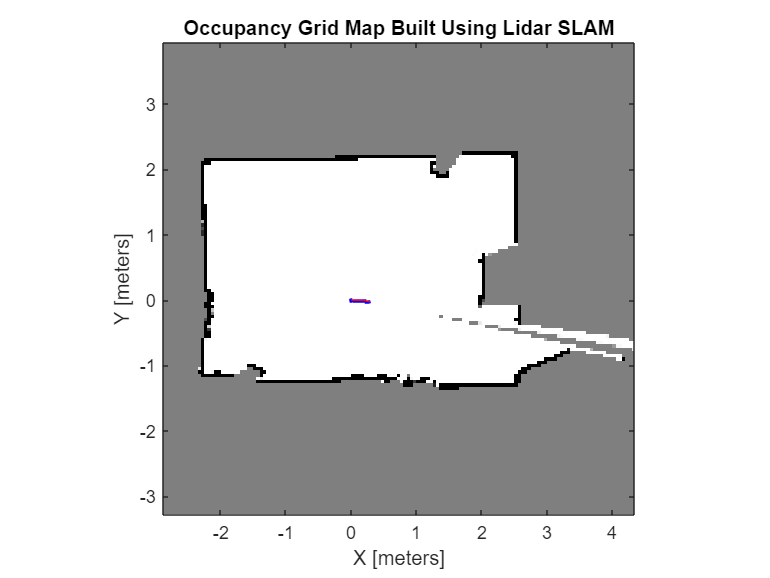

[scans, optimizedPoses]  = scansAndPoses(slamAlg);
map = buildMap(scans, optimizedPoses, mapResolution, maxLidarRange);
figure; 
show(map);
hold on
show(slamAlg.PoseGraph, 'IDs', 'off');
hold off
title('Occupancy Grid Map Built Using Lidar SLAM');